% example of dct denoising
clear
close all

% load the image and rescale it in [0,1]
% img = im2double(imread('cameraman.tif'));
% img = checkerboard(16, 8, 8);
% img = circshift(img, [1,1]);
% img = im2double(imread('BM3D_images/barbara.png'));
img = im2double(imread('C:/Users/simo9/Desktop/MMMIP/lez3_A_img_denoising/BM3D_images/Lena512.png'));

% noise level
sigma_noise = 20/255;

%patch size
p = 8;

% corrupt the image with white gaussian noise
noisy_img = img +  random('normal', 0, sigma_noise, size(img));

% compute the PSNR of the noisy input
psnr_noisy = 10 * log10(size(img,1)*size(img, 2)/sum((img - noisy_img).^2, "all"))

psnr_noisy = 22.1021

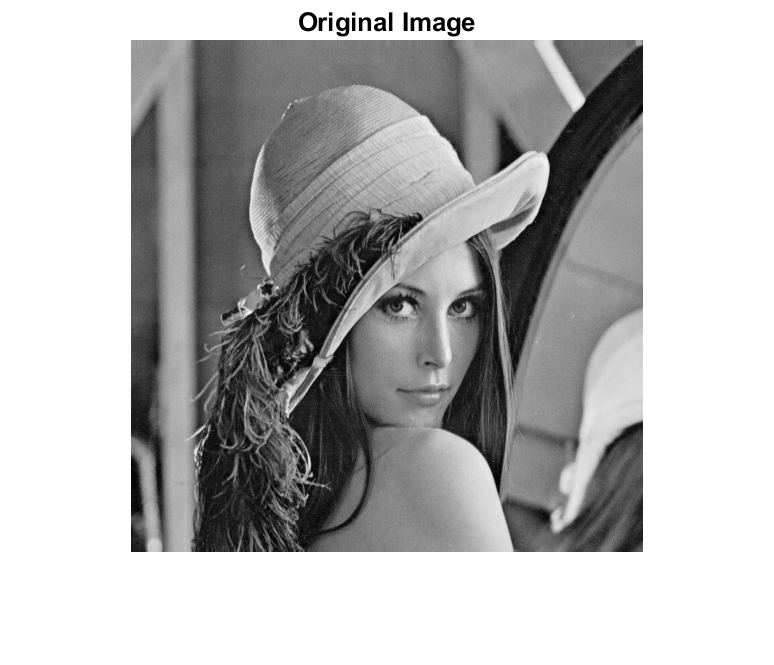


figure(1), imshow(img,[]), title('Original Image')

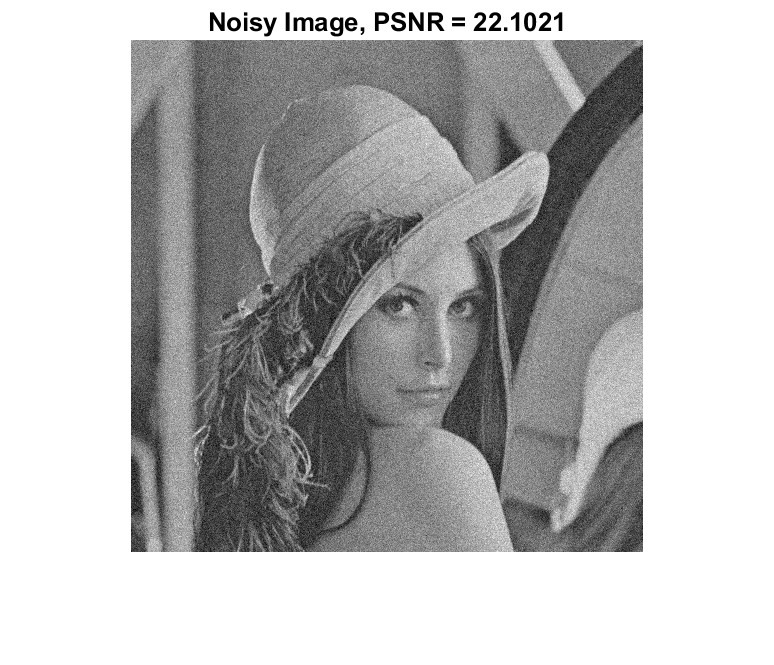

figure(2), imshow(noisy_img,[]), title(['Noisy Image, PSNR = ',num2str(psnr_noisy)])

## load the dictionary

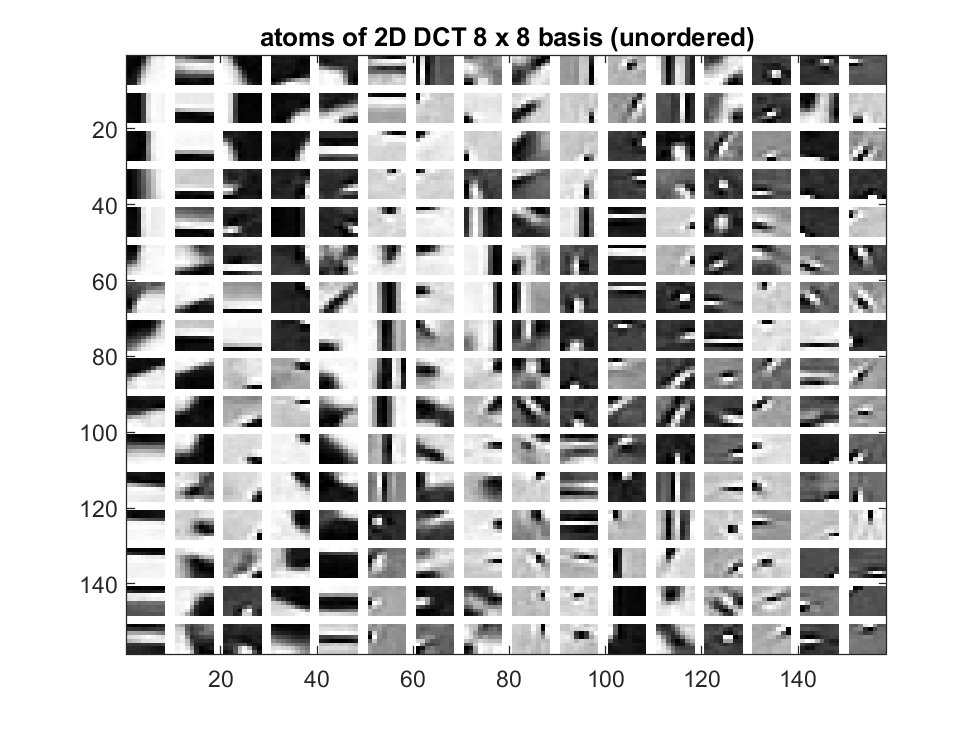

D = load('dict_nat_img.mat').D;

% display the 2D-DCT basis 
figure(), show_dictionary(D);
title(['atoms of 2D DCT ', num2str(p) ,' x ', num2str(p) , ' basis (unordered)'])

## denoising

% For this assignment I implemented some functions for the MP variants
% copy pasting the code from the previous lab

% initialize the estimated images
img_hat = zeros(size(noisy_img));

% initialize the weight matrix
weights = zeros(size(noisy_img));

% set the threshold for the sparse coding
tau = 1.15 * p * sigma_noise;
 
% define the step (=p for non overlapping patches)
STEP = 1; % STEP = 1 might be very time consuming, start with larger STEP

tic
% operates patch-wise
maxiter = 100;
for ii = 1 : STEP : (size(noisy_img,1)-p+1)
    for jj=1 : STEP : (size(noisy_img,1)-p+1)
        % extrach the patch with the top left corner at pixel (ii, jj)
        s  = noisy_img(ii:ii+p-1,jj:jj+p-1);
        
        % store and subtract the mean
        avg = mean(s, "all");
        
        
        % perform the sparse coding
        
        %The following functions return the estimated vector s_hat,
        %we just need to add the avg patch
        %[s_hat, resNorm] = MP(D, reshape(s - avg, p*p,1), tau, p*p, maxiter); %38.158341
        [s_hat, resNorm] = WMP(D, reshape(s - avg, p*p,1), tau, p*p, maxiter); %27 %remember to fix t
        %[s_hat, resNorm] = OMP(D, reshape(s - avg, p*p,1), tau, p*p); %65
        %[s_hat, resNorm] = LSOMP(D, reshape(s - avg, p*p,1), tau, p*p); %very time consuming
        % perform the reconstruction
        s_hat = reshape(s_hat, [p, p]) + avg;
        
        % put the reconstructed patch in the estimated image using the computed weight
        % UPDATE img_hat
        img_hat(ii:ii+p-1,jj:jj+p-1) = img_hat(ii:ii+p-1,jj:jj+p-1) + s_hat;
        % store the weight of the current patch in the weight matrix
        % UPDATE weights
        weights(ii:ii+p-1,jj:jj+p-1) = weights(ii:ii+p-1,jj:jj+p-1) + ones(size(s));
    end
end
toc

Elapsed time is 27.907709 seconds.



% normalize the estimated image with the computed weights
img_hat = img_hat./weights;

% compute the psnr of the estimated image
psnr_hat = 10*log10(size(img_hat, 1)*size(img_hat,2)/sum((img_hat - img).^2, "all"));
str = sprintf('PSNR : %2.3f', psnr_hat);
disp(['\n', str, '\n'])

\nPSNR : 32.092\n


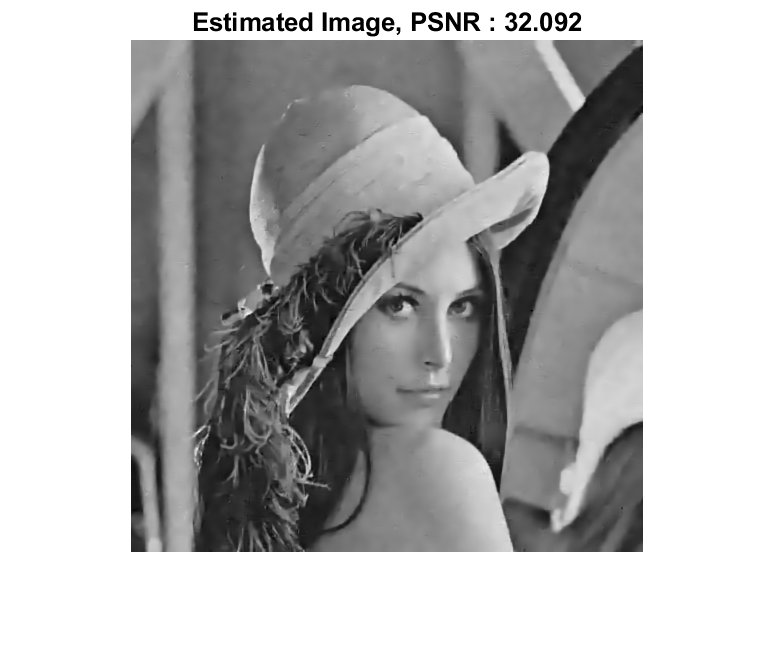

figure(3), imshow(img_hat,[]), title(['Estimated Image, ', str])